# Robotica Taller 2

*Daniel Esteban Ramirez Chiquillo*

*c.c. 1002479235*

*dramirezch@unal.edu.co*

## *1*

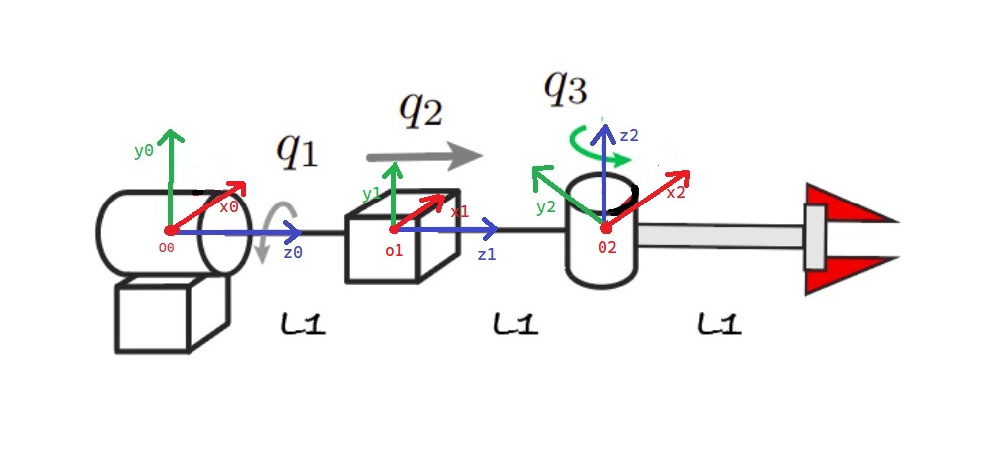

imshow("punto_1.jpg")

syms L1;
a = {0; 0; 0};
alpha = {0; 0; 90};
d = {0; L1; L1};
theta = {0; 0; 0};
table(a, alpha, d, theta)

ans = 3×4 table
      a      alpha       d       theta
    _____    ______    ______    _____

    {[0]}    {[ 0]}    {[ 0]}    {[0]}
    {[0]}    {[ 0]}    {[L1]}    {[0]}
    {[0]}    {[90]}    {[L1]}    {[0]}


## Funciones de ayuda

function [MTHtx] = mth_trans_x(dist)
    MTHtx = [1 0 0 dist; 0 1 0 0; 0 0 1 0; 0 0 0 1];
end

function [MTHty] = mth_trans_y(dist)
    MTHty = [1 0 0 0; 0 1 0 dist; 0 0 1 0; 0 0 0 1];
end

function [MTHtz] = mth_trans_z(dist)
    MTHtz = [1 0 0 0; 0 1 0 0; 0 0 1 dist; 0 0 0 1];
end

function [MTHrx] = mth_rot_x(ang)
    MTHrx = [1 0 0 0; 0 cosd(ang) -sind(ang) 0; 0 sind(ang) cosd(ang) 0; 0 0 0 1];
end

function [MTHry] = mth_rot_y(ang)
    MTHry = [cosd(ang) 0 sind(ang) 0; 0 1 0 0; -sind(ang) 0 cosd(ang) 0; 0 0 0 1];
end

function [MTHrz] = mth_rot_z(ang)
    MTHrz = [cosd(ang) -sind(ang) 0 0; sind(ang) cosd(ang) 0 0; 0 0 1 0; 0 0 0 1];
end

function [MTHt] = mth_trans(x,y,z)
    MTHt = mth_trans_x(x) * mth_trans_y(y) * mth_trans_z(z);
end

function [MTHr] = mth_rot(x,y,z)
    MTHr = mth_rot_x(x) * mth_rot_y(y) * mth_rot_z(z);
end

function [MTH] = mth(x,y,z, angx, angy, angz)
    MTH = mth_trans(x,y,z) * mth_rot(angx,angy,angz);
end

function [MTH_inv] = mth_inv(mth)
    R = mth(1:3, 1:3);
    d = mth(1:3, 4);
    MTH_inv = [R' -R'*d; 0 0 0 1];
end

function [MTH_DH] = mth_dh(theta_i, d_i, a_i, alpha_i)
    MTH_DH = mth_rot_z(theta_i) * mth_trans_z(d_i) * mth_trans_x(a_i) * mth_rot_x(alpha_i);
end
